**Validation du correcteur C(p) en simulation : **

**1) Fonction de transfert G(p) :**

Constantes : 

L = 2e-3

L = 0.0020

R = 1

R = 1

Ubatt = 24

Ubatt = 24

Formules : 

Tg =L/R

Tg = 0.0020

K = 1/R

K = 1

G(p) : 

G=tf([2*K*Ubatt],[Tg 1])

G =
 
      48
  -----------
  0.002 s + 1
 
Continuous-time transfer function.



**2) Fonction de transfert F(p) :  **

Constantes :

S  = 0.1041

S = 0.1041

R8 = 10e3 

R8 = 10000

R5 = 5.1e3

R5 = 5100

R12 = 10e3

R12 = 10000

R21 = 220

R21 = 220

R18 = 12e3

R18 = 12000

C2 = 22e-9

C2 = 2.2000e-08

C7 = 22e-9

C7 = 2.2000e-08

Formules : 

Kfiltre = (R8/(R5+R8)) * (1 + R18/R12)

Kfiltre = 1.4570

Tr1 = (R8 * R5 / ( R8 + R5)) * C2

Tr1 = 7.4305e-05

Tr2 = R21 * C7 

Tr2 = 4.8400e-06

F(p) : 

F=tf([Kfiltre*S],[Tr1*Tr2 Tr1+Tr2 1])

F =
 
              0.1517
  -------------------------------
  3.596e-10 s^2 + 7.914e-05 s + 1
 
Continuous-time transfer function.



**3) Fonction de transfert C(p) : **

Constantes : 

ft = 400

ft = 400

Formules : 

Tc3 = Tg

Tc3 = 0.0020

Tc4 = Ubatt*K*Kfiltre*S /(pi*ft) 

Tc4 = 0.0029

C(p) : 

C=tf([Tc3 1],[Tc4 0])

C =
 
  0.002 s + 1
  -----------
  0.002897 s
 
Continuous-time transfer function.



Fonction de transfert en boucle ouverte HBO : 

HBO = C*G*F

HBO =
 
                       0.01456 s + 7.28
  ----------------------------------------------------------
  2.083e-15 s^4 + 4.596e-10 s^3 + 6.023e-06 s^2 + 0.002897 s
 
Continuous-time transfer function.



Diagramme de bode : 

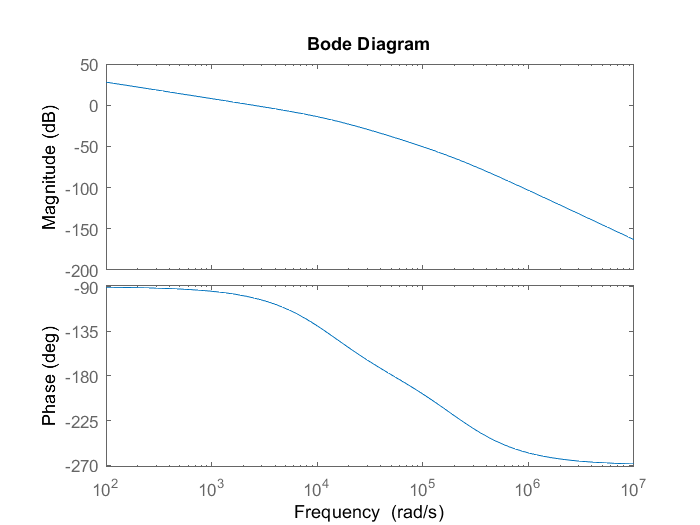

bode(HBO)